syms t(x,d,c)
t(x,d,c) = (sqrt(x^2+d^2)+d)/c

$$t(x, d, c) = \frac{d+\sqrt{d^{2}+x^{2}}}{c}$$

assume(-20e-3<=x & x<=20e-3)
assume(1450<=c & c<=1580)
assume(d<=50e-3)
basic_depth = 10e-3;%[m]
basic_sound_speed = 1580;%[m]
freq = 5e6;%[Hz]
syms d(c)
d(c) = basic_depth/basic_sound_speed*c

$$d(c) = \frac{934012358162509\,c}{147573952589676412928}$$

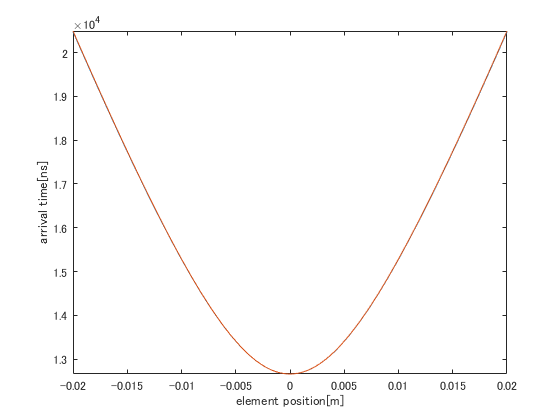

figure;
fplot(t(x,basic_depth,basic_sound_speed)*1e9)%[ns]
xlabel('element position[m]')
ylabel('arrival time[ns]')
hold on
differntial_sound_speed = 1578;
fplot(t(x,d(differntial_sound_speed),differntial_sound_speed)*1e9)%[ns]
xlim([-20e-3 20e-3])
hold off

figure;
fplot(t(x,d(differntial_sound_speed),differntial_sound_speed)*1e9-t(x,d(basic_sound_speed),basic_sound_speed)*1e9);
xlabel('素子位置[m]')
ylabel('$$|t(x,v,l)-\hat{t}(x)|$$[ns]','Interpreter','latex')
title('推定遅延曲線における誤差')
savefig("H:\result\2018_12_13_IMCL_direct_estimation_single_element\theoritical\estimation_error_1mm_2mPersec");
exportfig("H:\result\2018_12_13_IMCL_direct_estimation_single_element\theoritical\estimation_error_1mm_2mPersec",'png',[200 200]);


$$$$|t(x,v,l)-\hat{t}(x)|$$$$


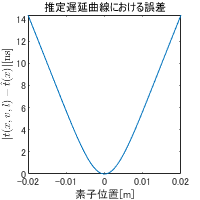

xlim([-20e-3 20e-3])

1/(freq)*1e9

ans = 200

time_36_degree = 1/(freq)*1e9/10

time_36_degree = 20

sampling_time = 1/(50e6)*1e9

sampling_time = 20

oversampling_time = sampling_time/4

oversampling_time = 5

約3 m/sの誤差であれば音速の推定可能性があると考えられる．

syms t(x,d,c)
t(x,d,c) = (sqrt(x^2+d^2)+d)/c

$$t(x, d, c) = \frac{d+\sqrt{d^{2}+x^{2}}}{c}$$

assume(-20e-3<=x & x<=20e-3)
assume(1450<=c & c<=1580)
assume(d<=50e-3)
basic_depth = 10e-3;%[m]
basic_sound_speed = 1580;%[m]
freq = 5e6;%[Hz]
syms d(c)
d(c) = basic_depth/basic_sound_speed*c

$$d(c) = \frac{934012358162509\,c}{147573952589676412928}$$

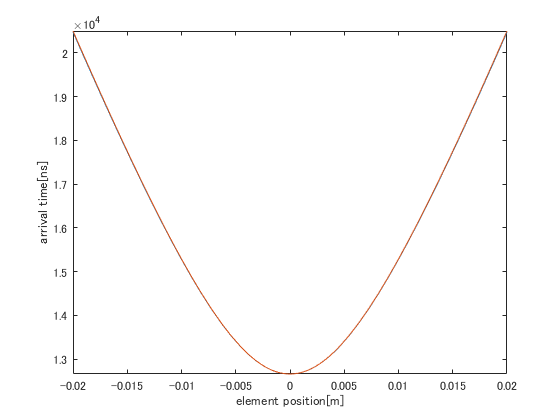

figure;
fplot(t(x,basic_depth,basic_sound_speed)*1e9)%[ns]
xlabel('element position[m]')
ylabel('arrival time[ns]')
hold on
differntial_sound_speed = 1577;
fplot(t(x,d(differntial_sound_speed),differntial_sound_speed)*1e9)%[ns]
xlim([-20e-3 20e-3])
hold off

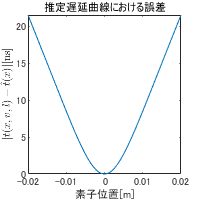

figure;
fplot(t(x,d(differntial_sound_speed),differntial_sound_speed)*1e9-t(x,d(basic_sound_speed),basic_sound_speed)*1e9);
xlabel('素子位置[m]')
ylabel('$$|t(x,v,l)-\hat{t}(x)|$$[ns]','Interpreter','latex')
title('推定遅延曲線における誤差')
savefig("H:\result\2018_12_13_IMCL_direct_estimation_single_element\theoritical\estimation_error_1mm_3mPersec");
exportfig("H:\result\2018_12_13_IMCL_direct_estimation_single_element\theoritical\estimation_error_1mm_3mPersec",'png',[200 200]);

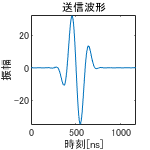

load("H:\data\kwave\result\2018_12_14_point_medium_various\boundary_2.0mm_IMCL4%\sourse_wave.mat")
load("H:\data\kwave\result\2018_12_14_point_medium_various\boundary_2.0mm_IMCL4%\kgrid.mat")
[~,num_sample] = size(source_wave);
% サンプル数を4倍にするためにスプライン補間
interp_sourcewave = interp1(source_wave,linspace(1,num_sample,num_sample*4)','spline');
interp_t = interp1(kgrid.t_array,linspace(1,num_sample,num_sample*4)','spline');
ind_inverse_t = linspace(length(interp_t),1,length(interp_t));
figure;
plot(interp_t*1e9,interp_sourcewave)
xlim([0.00000 1170])
ylim([-35.0 32.3])
xlabel('時刻[ns]')
ylabel('振幅')
title('送信波形')
auto_correlation = xcorr(interp_sourcewave)/(interp_sourcewave.'*interp_sourcewave);
savefig("H:\result\2018_12_13_IMCL_direct_estimation_single_element\theoritical\source_wave");
exportfig("H:\result\2018_12_13_IMCL_direct_estimation_single_element\theoritical\source_wave",'png',[150 150]);

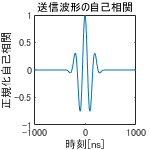

figure;

shift_t = cat(1,-interp_t(ind_inverse_t),interp_t(2:end));
plot(shift_t*1e9,auto_correlation);
xlabel('時刻[ns]')
ylabel('正規化自己相関')
title('送信波形の自己相関')
xlim([-1000 1000])
savefig("H:\result\2018_12_13_IMCL_direct_estimation_single_element\theoritical\auto_correlation");
exportfig("H:\result\2018_12_13_IMCL_direct_estimation_single_element\theoritical\auto_correlation",'png',[150 150]);

lによる音速推定誤差をプロットする．

syms t(x,d,c)
syms L(d)
syms dc(l)
syms x0
syms c0
syms dt
x0 = 20e-3;%[m]
dt

$$dt = \mathrm{dt}$$


% c0 = 1580;%[m/s]
t(x,d,c) = (sqrt(x^2+d^2)+d)/c

$$t(x, d, c) = \frac{d+\sqrt{d^{2}+x^{2}}}{c}$$

assume(-20e-3<=x & x<=20e-3)
assume(1450<=c & c<=1580)
assume(d<=50e-3)
L(d) =  sqrt(x0^2+d^2)+d

$$L(d) = d+\sqrt{d^{2}+\frac{1}{2500}}$$

basic_depth = 10e-3;%[m]
basic_sound_speed = 1580;%[m]
freq = 5e6;%[Hz]
syms d(c)
d(c) = basic_depth/basic_sound_speed*c

$$d(c) = \frac{934012358162509\,c}{147573952589676412928}$$

dc(l) = (dt*(c0^2))/(dt*c0+l)

$$dc(l) = \frac{{c_{0}}^{2}\,\mathrm{dt}}{l+c_{0}\,\mathrm{dt}}$$

dt = 20e-9

dt = 2.0000e-08

c0 = 1580

c0 = 1580

dc(l) = (dt*(c0^2))/(dt*c0+d)

$$dc(l) = \frac{1798845777562833}{36028797018963968\,\left(\frac{934012358162509\,c}{147573952589676412928}+\frac{4663336901833775}{147573952589676412928}\right)}$$

fplot(t(x,d(differntial_sound_speed),differntial_sound_speed)*1e9)%[ns]

関数または変数 'differntial_sound_speed' が未定義です。

xlabel('送信素子からワイヤまでの長さ [mm]')
ylabel('$$max|t(x,v,l)-\hat{t}(x)|$$[ns]','Interpreter','latex')

% syms dc(d)
% syms x0
% syms c0
% syms dt
% sym d
% assume(0<d & d<=50e-3)
xmax = 20e-3;%[m]
c0 = 1580;%[m]
dt = 20e-9

dt = 2.0000e-08

d = linspace(0,50e-3,100);
dc = abs(xmax./sqrt((dt+(d+sqrt(d.^2+xmax^2))/c0).^2-2.*d/c0.*(dt+(d+sqrt(d.^2+xmax^2))/c0)) -c0)

dc =     2.4925    2.4933    2.4956    2.4996    2.5051    2.5122    2.5208    2.5310    2.5427    2.5558    2.5705    2.5865    2.6040    2.6229    2.6431    2.6647    2.6876    2.7117    2.7370    2.7636    2.7913    2.8201    2.8500    2.8810    2.9130    2.9460    2.9799    3.0148    3.0505    3.0871    3.1246    3.1628    3.2018    3.2416    3.2820    3.3232    3.3650    3.4074    3.4505    3.4941    3.5384    3.5831    3.6284    3.6742    3.7205    3.7673    3.8145    3.8621    3.9102    3.9587


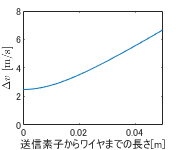

plot(d,dc)%[ms]
xlim([0 50e-3])
ylim([0 8])
xlabel('送信素子からワイヤまでの長さ[m]')
ylabel('$$\Delta{v}\\$$ [m/s]','Interpreter','latex')
savefig("H:\result\2018_12_13_IMCL_direct_estimation_single_element\theoritical\precision_vs_depth");
exportfig("H:\result\2018_12_13_IMCL_direct_estimation_single_element\theoritical\precision_vs_depth",'png',[180 150]);

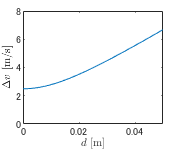

plot(d,dc)%[ms]
xlim([0 50e-3])
ylim([0 8])
xlabel('$$d\\$$ [m]','Interpreter','latex')
ylabel('$$\Delta{v}\\$$ [m/s]','Interpreter','latex')
savefig("H:\result\2018_12_13_IMCL_direct_estimation_single_element\theoritical\precision_vs_depth2");
exportfig("H:\result\2018_12_13_IMCL_direct_estimation_single_element\theoritical\precision_vs_depth2",'png',[180 150]);